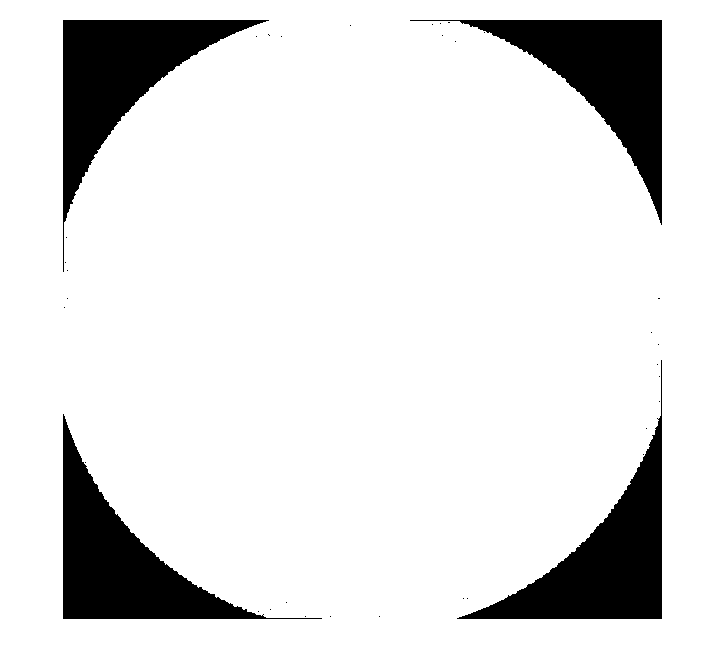

clc
clear
close all

A=(single(imread('640.bmp')));
A=imrotate(A,-0.8,"crop");
%A=(A-min(min(A)))/(max(max(A))-min(min(A)));
D=imread('1.jpg');
D=gpuArray(single(D(:,:,1)));
C=gpuArray(single(zeros(size(A))));
imshow(A,[])

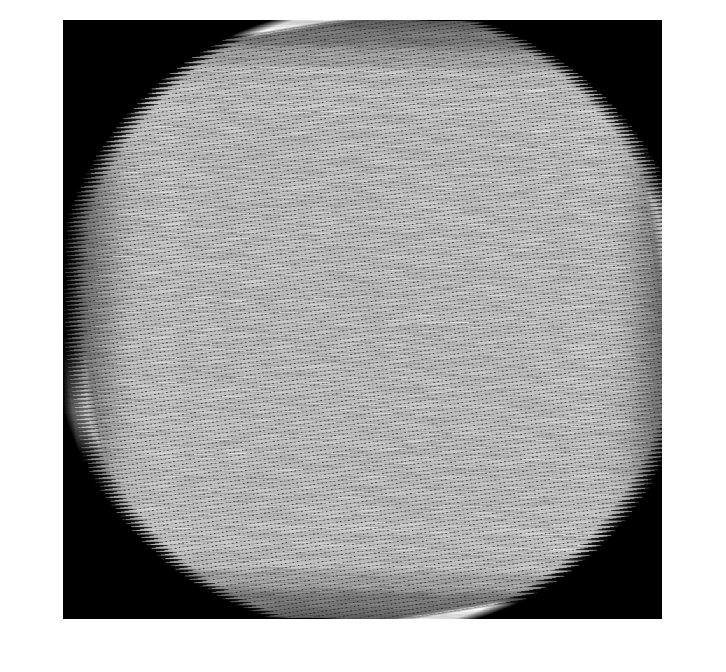

for ii=1:255
    B=imtranslate(A,[ii,0]);
    C=B+C;
    if mod(ii,20)==0
        imshow(C,[])
    end
end

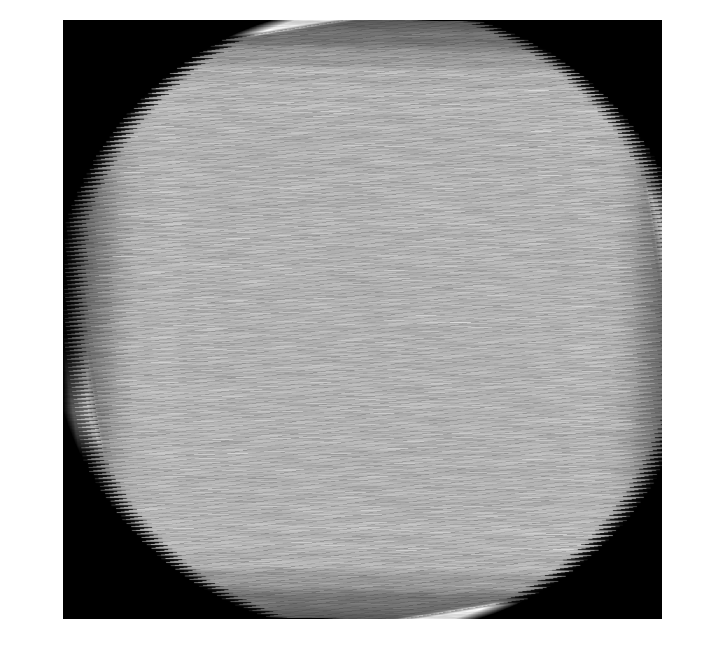

imshow(C,[])